# **Integrarea Gauss**

Este o tehnica de integrare numerica optimizata pentru functii poderate, adica pentru functii de forma:

####         
$$\int_a^b f\left(x\right)\cdot w\left(x\right)\textrm{dx}$$


**Spre deosebire de metodele compuse/adaptive, metodele Gauss:**

- aleg **noduri și coeficienți** astfel încât integrarea unui polinom de grad cât mai mare să fie exactă

- sunt **optime** pentru o clasă fixă de ponderi și intervale

### Clasificarea generala a metodelor

## 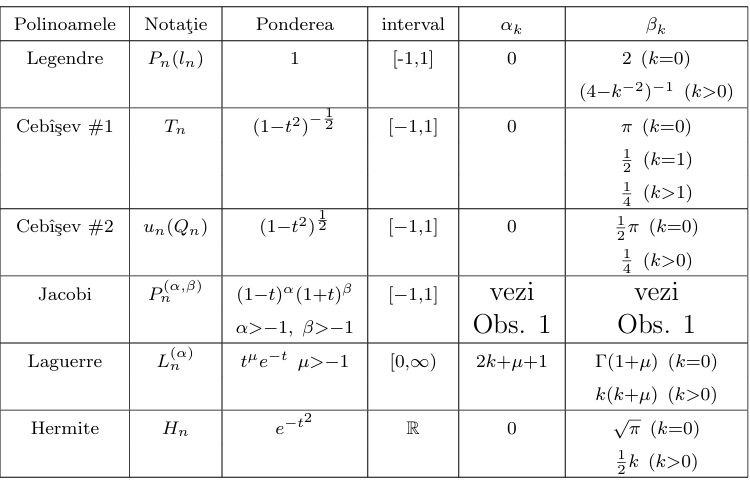

# **Gauss Legendre**

**Interval:** [−1,1], extensibil la orice [a,b]

**Pondere:** w(x)=1

**Când o folosești:**

Pentru integrale **standard** definite pe un interval finit, fără ponderi speciale.

**Avantaje:**

- Nu necesită ponderi în funcție

- Precizie mare cu puține noduri

- Adaptabilă pe orice interval prin schimbare de variabilă

#### 
$$\int_{-1}^1 f\left(x\right)\textrm{dx}\approx \sum_{k=1}^n A_k \cdot f\left(x_k \right)$$


% Setari
eps = 1e-7;
% Intervalul integralei
a = 1; 
b = 2;

% Functii de integrat
f1 = @(x) sin(x.^2);

fprintf("\n Integrala:\n");


 Integrala:


fprintf("   ∫ sin(x^2) dx\n");

   ∫ sin(x^2) dx


fprintf("   Formula Gauss-Legendre :\n");

   Formula Gauss-Legendre :


fprintf("      I ≈ Σ A_k * f(x_k),  k = 1..n\n");

      I ≈ Σ A_k * f(x_k),  k = 1..n



[I1, n1] = integrare_legendre_adaptiv(f1, a, b, eps);
[x1, A1] = gauss_legendre(n1);
t1 = ((b - a)/2) * x1 + (a + b)/2;  % transformare noduri

fprintf("   Precizie ceruta: ε = %.0e\n", eps);

   Precizie ceruta: ε = 1e-07


fprintf("   Numar de noduri necesar: n = %d\n", n1);

   Numar de noduri necesar: n = 7


fprintf("   Noduri x_k (transformate):\n"); disp(t1');

   Noduri x_k (transformate):
   1.025446043828621   1.129234407200303   1.297077424311301   1.500000000000000   1.702922575688699   1.870765592799697   1.974553956171379



fprintf("   Coeficienti A_k:\n"); disp(((b - a)/2) * A1);

   Coeficienti A_k:
   0.064742483084435   0.139852695744638   0.190915025252560   0.208979591836734   0.190915025252559   0.139852695744638   0.064742483084435




fprintf("   Rezultat aproximativ: %.10f\n", I1);

   Rezultat aproximativ: 0.4945081877


# **Gauss Cebisev 1**

**Interval:** [−1,1]

**Pondere:** $w\left(x\right)=\frac{1}{\sqrt{1-x^2 }}$

**Când o folosești:**

Pentru funcții de forma:

#### 
$$\int_{-1}^1 \frac{f\left(x\right)}{\sqrt{\;1-x^2 }}\textrm{dx}$$


f = @(x) x .* exp(-x.^2);  % functie fara pondere
n = 10;
a = -1; 
b = 1;
eps = 1e-16;

[I, I_ex, err] = integrare_chebyshev1(f, n, a, b, eps);

fprintf("→ Cuadratura Gauss-Chebyshev I cu n = %d noduri\n", n);

→ Cuadratura Gauss-Chebyshev I cu n = 10 noduri


fprintf("→ Intervalul: [%g, %g]\n", a, b);

→ Intervalul: [-1, 1]


fprintf("→ Valoare exacta numerica: %.10f\n", I_ex);

→ Valoare exacta numerica: -0.0000000000


fprintf("→ Aproximare prin cuadratura: %.10f\n", I);

→ Aproximare prin cuadratura: 0.0000000000


fprintf("→ Eroare absoluta: %.2e\n", err);

→ Eroare absoluta: 1.11e-16



if abs(I) < 1e-14
    fprintf(" Integrala ≈ 0: functia este impara pe un interval simetric.\n");
end

 Integrala ≈ 0: functia este impara pe un interval simetric.


# **Gauss Cebisev 2**

**Interval:** [−1,1]

**Pondere:** $w\left(x\right)=\sqrt{1-x^2 }$

**Când o folosești:**

Pentru funcții de forma:

#### 
$$\int_{-1}^1 f\left(x\right)\cdot \sqrt{\;1-x^2 }\textrm{dx}$$


% Functia f(x) din integrandul: ∫_{-1}^{1} sqrt(1 - x^2) * f(x) dx
f = @(x) exp(-x.^2);
n = 10;
a = -1;
b = 1;
eps = 1e-12;

[I, I_ex, err] = integrare_chebyshev2(f, n, a, b, eps);

fprintf("→ Cuadratura Gauss-Chebyshev II pe [%g, %g], n = %d\n", a, b, n);

→ Cuadratura Gauss-Chebyshev II pe [-1, 1], n = 10


fprintf("→ Valoare exactă (numerică): I_ex = %.10f\n", I_ex);

→ Valoare exactă (numerică): I_ex = 1.2589242566


fprintf("→ Aproximare cuadratură:     I ≈ %.10f\n", I);

→ Aproximare cuadratură:     I ≈ 1.2589242566


fprintf("→ Eroare absolută:            %.2e\n", err);

→ Eroare absolută:            2.63e-13



if abs(I) < 1e-14
    fprintf(" Integrala ≈ 0: functia este impara pe un interval simetric.\n");
end

# **Gauss Jabobi**

**Interval:** [−1,1]

**Pondere:** $w\left(x\right)={\left(1-x\right)}^{\alpha } {\left(1+x\right)}^{\beta }$

**Când o folosești:**

Pentru funcții ce au **singularități la capetele intervalului**, cum e 1/ $\sqrt{\;\sin \left(x\right)}$    

**Se remarcă prin:**

- Control fin asupra comportamentului la capete

- Versatilitate prin parametrii $\alpha ,\beta$

% Setari problema
n = 15;
alpha = -0.5;
beta = 0;
a = 0;
b = pi/2;
f = @(x) 1;  % restul e inclus in pondere
w = @(x) 1 ./ sqrt(sin(x));
valoare_exacta = integral(@(x) 1 ./ sqrt(sin(x)), 0, pi/2, 'AbsTol', 1e-14);

% Apelam functie generalizata
[I, err] = integrare_jacobi_custom(f, n, alpha, beta, a, b, w, valoare_exacta);

fprintf(" Cuadratura Gauss-Jacobi pe [%g, %g] cu α = %.1f, β = %.1f, n = %d\n", ...
    a, b, alpha, beta, n);

 Cuadratura Gauss-Jacobi pe [0, 1.5708] cu α = -0.5, β = 0.0, n = 15


fprintf("→ Aproximare:%.10f   Valoare exacta:%.10f (eroare: %.2e)\n", I, valoare_exacta, err);

→ Aproximare:0.5731111007   Valoare exacta:1.3281980806 (eroare: 2.07e+00)
→ Aproximare:2.7906263521   Valoare exacta:3.4813552904 (eroare: 4.14e+00)
→ Aproximare:4.7451870072   Valoare exacta:5.3048878881 (eroare: 5.81e+00)
→ Aproximare:6.2502547115   Valoare exacta:6.6258991788 (eroare: 6.93e+00)
→ Aproximare:7.1632424693   Valoare exacta:7.3192452647 (eroare: 7.40e+00)
→ Aproximare:2.6220575543   Valoare exacta:2.0489464536 (eroare: 1.29e+00)
→ Aproximare:0.5517215746   Valoare exacta:0.1685687979 (eroare: 8.59e-01)
→ Aproximare:1.5131294479   Valoare exacta:2.1231294529 (eroare: 2.68e+00)
→ Aproximare:3.1862986097   Valoare exacta:3.6281971572 (eroare: 4.00e+00)
→ Aproximare:4.3092500238   Valoare exacta:4.5411849150 (eroare: 4.70e+00)
→ Aproximare:4.7756047305   Valoare exacta:

# **Gauss Laguerre**

**Interval:** [0,∞)

**Pondere:** $w\left(x\right)=e^{-x}$

**Când o folosești:**

Pentru funcții de forma:

#### 
$$\int_0^{\infty } f\left(x\right)\cdot e^{-x} \textrm{dx}\approx \sum_{k=1}^n A_k \cdot f\left(x_k \right)$$


% Functii f(x), fara ponderea e^{-x}
f1 = @(x) sin(x);
f2 = @(x) cos(x);

n = 20;
a = 0; 
b = Inf;
eps = 1e-12;

[I1, Iex1, err1] = integrare_laguerre(f1, n, a, b, eps);
[I2, Iex2, err2] = integrare_laguerre(f2, n, a, b, eps);

fprintf(" Cuadratura Gauss-Laguerre cu n = %d noduri pe [%g, ∞)\n", n, a);

 Cuadratura Gauss-Laguerre cu n = 20 noduri pe [0, ∞)


fprintf("→ ∫₀^∞ e^{-x} sin(x) dx ≈ %.10f   (exact: %.10f)   | eroare: %.2e\n", I1, Iex1, err1);

→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -5.29e-23
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.73e-18
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -2.22e-16
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.67e-16
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -1.95e-18
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: -5.29e-23
→ ∫₀^∞ e^{-x} sin(x) dx ≈ -0.0000000000   (exact: -0.0000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.5000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} sin(x) dx ≈ 0.5000000000   (exact: 0.50000

fprintf("→ ∫₀^∞ e^{-x} cos(x) dx ≈ %.10f   (exact: %.10f)   | eroare: %.2e\n", I2, Iex2, err2);

→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000000000   (exact: 0.0000000004)   | eroare: 9.71e-08
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000069739   (exact: 0.0002040888)   | eroare: 2.90e-03
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0221756130   (exact: 0.0974394443)   | eroare: 2.56e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4131528218   (exact: 0.4131528218)   | eroare: 2.56e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0974394443   (exact: 0.0221756130)   | eroare: 2.90e-03
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0002040888   (exact: 0.0000069739)   | eroare: 9.71e-08
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0000000004   (exact: 0.0000000000)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.5000000000   (exact: 0.4999999996)   | eroare: 5.00e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4999930261   (exact: 0.4997959112)   | eroare: 4.97e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4778243870   (exact: 0.4025605557)   | eroare: 2.44e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.0868471782   (exact: 0.0868471782)   | eroare: 2.44e-01
→ ∫₀^∞ e^{-x} cos(x) dx ≈ 0.4025605557   (exact: 0.4778243870)   | eroare: 4

# **Gauss Hermite**

**Interval:** (−∞,∞)

**Pondere:** $w\left(x\right)=e^{-x^2 }$

**Când o folosești:**

Pentru integrale pe tot axul real:

#### 
$$\int_0^{\infty } f\left(x\right)\cdot e^{-x^2 } \textrm{dx}$$


n = 20;

% f(x) = sin(x)
f1 = @(x) sin(x);
exact1 = 0;  % integrala functiei impare pe R => 0

% f(x) = cos(x)
f2 = @(x) cos(x);
exact2 = sqrt(pi) * exp(-1/4);

[I1, err1] = integrare_hermite(f1, n, exact1);
[I2, err2] = integrare_hermite(f2, n, exact2);

fprintf(" Cuadratura Gauss-Hermite (n = %d)\n", n);

 Cuadratura Gauss-Hermite (n = 20)


fprintf("→ ∫ e^{-x^2} sin(x) dx ≈ %.10f   | eroare: %.2e\n", I1, err1);

→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 9.82e-25
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.78e-20
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 6.94e-18
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.50e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 8.33e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 7.77e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.78e-17
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 4.61e-19
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.99e-22
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 5.30e-28
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 9.82e-25
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 1.78e-20
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 6.94e-18
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.50e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 8.33e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 7.77e-16
→ ∫ e^{-x^2} sin(x) dx ≈ 0.0000000000   | eroare: 2.78e-

fprintf("→ ∫ e^{-x^2} cos(x) dx ≈ %.10f   | eroare: %.2e\n", I2, err2);

→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000000000   | eroare: -7.51e-10
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000001854   | eroare: -1.33e-05
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0003897937   | eroare: -5.54e-03
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0423536907   | eroare: -1.86e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.4893797169   | eroare: -7.89e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.7890896568   | eroare: -4.89e-01
→ ∫ e^{-x^2} cos(x) dx ≈ -0.1861017367   | eroare: -4.24e-02
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0055373998   | eroare: -3.90e-04
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000133196   | eroare: -1.85e-07
→ ∫ e^{-x^2} cos(x) dx ≈ -0.0000000008   | eroare: -3.81e-13
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3803884470   | eroare: 1.38e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3803886324   | eroare: 1.38e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.3807782407   | eroare: 1.39e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.4227421377   | eroare: 1.57e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.8697681639   | eroare: 2.17e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 2.1694781039   | eroare: 1.87e+00
→ ∫ e^{-x^2} cos(x) dx ≈ 1.566490183